clear

addpath("matlab_functions\")

method = "Analytical";

#### Compute Sensitivity

if strcmpi(method, 'Analytical')
    [Plate, Coil, Sensor] = myModel;
else
    [Plate, Coil, Sensor, Model] = myModel;
    mesh_size = 2; % 1:finest 9:coarsest
end

for freq = [900 225 100 55]
    if strcmpi(method, 'Analytical')
        S = ComputeSensitivityAnalytical(Plate, Coil, Sensor, freq);
    else
        S = ComputeSensitivityFEM(Model, Plate, Coil, Sensor, freq, mesh_size);
    end
    
    element_centers = Plate.elems_center;
    
    fname = sprintf('data/Sensitivity_%dHz_%s.mat', freq, datetime('now','Format','MMdd-HHmm'));
    save(fname, 'S','element_centers')
end

Compute coil took 34.65 seconds
Compute sensor 1 took 2.29 seconds
Compute sensor 2 took 2.26 seconds
Compute sensor 3 took 2.28 seconds
Compute sensor 4 took 2.32 seconds
Compute sensor 5 took 2.26 seconds
Compute sensor 6 took 2.33 seconds
Compute sensor 7 took 2.35 seconds
Compute sensor 8 took 2.29 seconds
Compute sensor 9 took 2.31 seconds
Compute sensor 10 took 2.25 seconds
Compute sensor 11 took 2.28 seconds
Compute sensor 12 took 2.25 seconds
Compute sensor 13 took 2.27 seconds
Compute sensor 14 took 2.25 seconds
Compute sensor 15 took 2.28 seconds
Compute sensor 16 took 2.28 seconds
Compute sensor 17 took 2.24 seconds
Compute sensor 18 took 2.26 seconds
Compute sensor 19 took 2.26 seconds
Compute sensor 20 took 2.36 seconds
Compute sensor 21 took 2.37 seconds
Compute sensor 22 took 2.32 seconds
Compute sensor 23 took 2.29 seconds
Compute sensor 24 took 2.27 seconds
Compute sensor 25 took 2.23 seconds
Compute sensor 26 took 2.25 seconds
Compute sensor 27 took 2.38 seconds
Compu


clear method mesh_size freq fname element_centers

#### Visualize Sensitivity

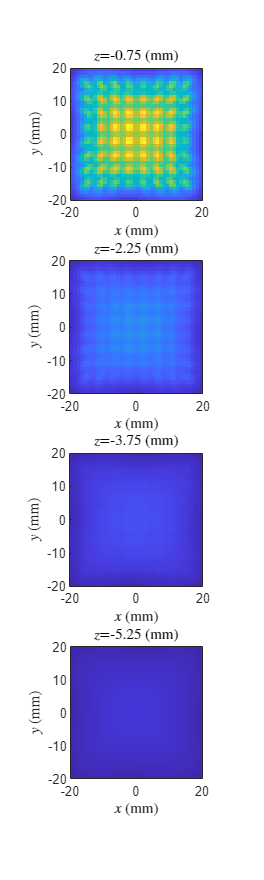

load('data\Sensitivity_100Hz_0221-1041.mat')
VisualizeSensitivity(S, element_centers)

function S = ComputeSensitivityFEM(Model, Plate, Coil, Sensor, freq, mesh_size)

S = zeros(size(Sensor.positions,2), size(Plate.gauss_points,3));

tic
ComsolModel('SolveCoil', Model, Coil, freq, mesh_size);
E1 = ComsolModel('InterpField', Model, 'E', Plate.gauss_points);
fprintf('Compute coil took %.2f seconds\n', toc)

for i = 1:size(Sensor.positions,2)
    Sensor.compute_index = i;

    tic
    ComsolModel('SolveSensor', Model, Sensor, freq, mesh_size);
    E2 = ComsolModel('InterpField', Model, 'E', Plate.gauss_points);
    fprintf('Compute sensor %d took %.2f seconds\n', i, toc)
    
    S(i,:) = sum(dot(E1,E2) .* Plate.gauss_weights, 2);    
end

end

function S = ComputeSensitivityAnalytical(Plate, Coil, Sensor, freq)

omega = 2*pi * freq;
S = zeros(size(Sensor.positions,2), size(Plate.gauss_points,3));

tic
E1 = zeros(size(Plate.gauss_points));
for j = 1:size(Plate.gauss_points,2)
for k = 1:size(Plate.gauss_points,3)
    E1(:,j,k) = CoilElectricField(Plate.gauss_points(:,j,k));
end
end
fprintf('Compute coil took %.2f seconds\n', toc)

for i = 1:size(Sensor.positions,2)
    Sensor.compute_index = i;

    tic
    E2 = zeros(size(Plate.gauss_points));
    r = Plate.gauss_points;
    for zi = reshape(unique(r(3,:,:)), 1,[])
        mask = r(3,:,:) == zi;
        [E2(1,mask), E2(2,mask)] = SensorElectricField(r(1,mask), r(2,mask), r(3,mask));
    end
    fprintf('Compute sensor %d took %.2f seconds\n', i, toc)
    
    S(i,:) = sum(dot(E1,E2) .* Plate.gauss_weights, 2);    
end

    function E = CoilElectricField(pos)
        if ~isfield(Coil, 'model')
            if Coil.fillet ~= Coil.width / 2
                error('Only support cylindrical coil')
            end
            zc = unique(Coil.positions(3,:));
            if numel(zc) ~= 1
                error('Coils must be at the same z position')
            end
            r2 = Coil.width / 2;
            r1 = r2 - Coil.thickness;
            z2 = zc + Coil.height / 2;
            z1 = zc - Coil.height / 2;
            N = Coil.N_turns;
            sigma = Plate.conductivity;
            mur = Plate.relative_permeability;
            d = Plate.height;
            
            Coil.model = CoilAbovePlate(r1,r2,z1,z2,N, sigma,mur,d);
        end
        E = zeros(3,1);
        for p = 1:size(Coil.positions,2)
            [theta,r,z] = cart2pol(pos(1)-Coil.positions(1,p), pos(2)-Coil.positions(2,p), pos(3));
            E_theta = Coil.model.E_theta(r,z, omega) * Coil.current(p);
            E(1) = E(1) + E_theta * -sin(theta);
            E(2) = E(2) + E_theta *  cos(theta);
        end
    end

    function [Ex,Ey] = SensorElectricField(x,y,z)
        if ~isfield(Sensor, 'model')
            Sensor.model = {};
        end
        p = Sensor.compute_index;
        if length(Sensor.model) < p || isempty(Sensor.model{p})
            sigma = Plate.conductivity;
            mur = Plate.relative_permeability;
            d = Plate.height;
            Sensor.model{p} = SensorAbovePlate(Sensor.positions(3,p), Sensor.axes(:,p), sigma,mur,d);
        end
        x = x - Sensor.positions(1,p);
        y = y - Sensor.positions(2,p);
        [Ex,Ey] = Sensor.model{p}.E(x,y,z, omega);
    end

end

function VisualizeSensitivity(S, element_centers)

z = unique(element_centers(3,:));
z = sort(z, 'descend');

scale = 1e3;

S_norm = vecnorm(S);

figure('Position',[10 10 300 250*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c = reshape(S_norm(mask), sqrt(sum(mask)),[]);

    xlim = [min(element_centers(1,mask)) max(element_centers(1,mask))] * scale;
    ylim = [min(element_centers(2,mask)) max(element_centers(2,mask))] * scale;

    subplot(length(z),1,k)
    imagesc(xlim,ylim, c.', [0 max(S_norm)])
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end

end